# Examine Well-Trained Session using Temporal Field Bayes - Time-in-Position Coding

fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

binSize = 200;
dsRate = 50;
trlWindow = {[-800 2000]};
alignment = {'PokeIn'};
% trlWindow = {[-2000 800]};
% alignment = {'PokeOut'};
bayesType = 1; 
%bayseTypes: 1 = Poisson: use with raw spike counts; 2 = Bernoulli: use with binarized spike counts; 3 = Gaussian: Use with z-scored spike counts

numChancePerms = 100;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);


% trialWindowed = true;
trialWindowed = false;
 %#ok<*UNRCH> 

## Compile Data

tic;
for ani = 1:length(fileDirs)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1 
        % Behavior Variables
        fiscPokeOutLat = cell(length(fileDirs),1);
        fiscRwdDelivLat = cell(length(fileDirs),1);
        % Posteriors
        realPost = cell(mlb.seqLength, 1, length(fileDirs));
        % Chance PDFs
        chancePDF_Full = cell(mlb.seqLength, 1);
        chancePDF_Pos = cell(mlb.seqLength, 1);
        chancePDF_Time = cell(mlb.seqLength, 1);
        % Chance Marginal Position
        chancePos_Full = cell(mlb.seqLength, 1);
        chancePos_Pos = cell(mlb.seqLength, 1);
        chancePos_Time = cell(mlb.seqLength, 1);
        % Chance Marginal Timing
        chanceTime_Full = cell(mlb.seqLength, 1);
        chanceTime_Pos = cell(mlb.seqLength, 1);
        chanceTime_Time = cell(mlb.seqLength,1);
    end
    mlb.binSize = binSize;
    mlb.dsRate = dsRate;
    mlb.windows = trlWindow;
    mlb.alignments = alignment;
    mlb.bayesType = bayesType;
    
    fiscPokeOutLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeOutIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    fiscRwdDelivLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).RewardIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    
    % Process Observations - FISC via Leave-1-Out
    mlb.SetLikes_FISC;
    mlb.Process_Observes;
    tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
    realPost(:,1,ani) = tempPosts(logical(eye(mlb.seqLength)));
    %% Process Chance
    fprintf('.... processing chance.... ');
    for perm = 1:numChancePerms 
        mlb.Process_Observes('Full');
        tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
        tempChanceFull = tempPosts(logical(eye(mlb.seqLength)));
        mlb.Process_Observes('Trial');
        tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
        tempChancePos = tempPosts(logical(eye(mlb.seqLength)));
        mlb.Process_Observes('Time');
        tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
        tempChanceTime = tempPosts(logical(eye(mlb.seqLength)));
        
        tempPos_Full = cell(mlb.seqLength,1);
        tempPos_Pos = cell(mlb.seqLength,1);
        tempPos_Time = cell(mlb.seqLength,1);

        tempTime_Full = cell(mlb.seqLength,1);
        tempTime_Pos = cell(mlb.seqLength,1);
        tempTime_Time = cell(mlb.seqLength,1);
        for pos = 1:mlb.seqLength
            tempPos_Full{pos} = mean(mlb.TabulateBayesPost(tempChanceFull{pos}, mlb.decodeIDvects(:,3)),3,'omitnan');
            tempPos_Pos{pos} = mean(mlb.TabulateBayesPost(tempChancePos{pos}, mlb.decodeIDvects(:,3)),3,'omitnan');
            tempPos_Time{pos} = mean(mlb.TabulateBayesPost(tempChanceTime{pos}, mlb.decodeIDvects(:,3)),3,'omitnan');

            tempTime_Full{pos} = mean(mlb.TabulateBayesPost(tempChanceFull{pos}, mlb.decodeIDvects(:,1)),3,'omitnan');
            tempTime_Pos{pos} = mean(mlb.TabulateBayesPost(tempChancePos{pos}, mlb.decodeIDvects(:,1)),3,'omitnan');
            tempTime_Time{pos} = mean(mlb.TabulateBayesPost(tempChanceTime{pos}, mlb.decodeIDvects(:,1)),3,'omitnan');

            tempChanceFull{pos} = mean(tempChanceFull{pos},3,'omitnan');
            tempChancePos{pos} = mean(tempChancePos{pos},3,'omitnan');
            tempChanceTime{pos} = mean(tempChanceTime{pos},3,'omitnan');
        end

        if ani == 1 && perm == 1
            chancePDF_Full(:,1) = tempChanceFull;
            chancePDF_Pos(:,1) = tempChancePos;
            chancePDF_Time(:,1) = tempChanceTime;

            chancePos_Full(:,1) = tempPos_Full;
            chancePos_Pos(:,1) = tempPos_Pos;
            chancePos_Time(:,1) = tempPos_Time;

            chanceTime_Full(:,1) = tempTime_Full;
            chanceTime_Pos(:,1) = tempTime_Pos;
            chanceTime_Time(:,1) = tempTime_Time;
        else
            for pos = 1:mlb.seqLength
                chancePDF_Full{pos} = chancePDF_Full{pos} + tempChanceFull{pos};
                chancePDF_Pos{pos} = chancePDF_Pos{pos} + tempChancePos{pos};
                chancePDF_Time{pos} = chancePDF_Time{pos} + tempChanceTime{pos};

                chancePos_Full{pos} = chancePos_Full{pos} + tempPos_Full{pos};
                chancePos_Pos{pos} = chancePos_Pos{pos} + tempPos_Pos{pos};
                chancePos_Time{pos} = chancePos_Time{pos} + tempPos_Time{pos};

                chanceTime_Full{pos} = chanceTime_Full{pos} + tempTime_Full{pos};
                chanceTime_Pos{pos} = chanceTime_Pos{pos} + tempTime_Pos{pos};
                chanceTime_Time{pos} = chanceTime_Time{pos} + tempTime_Time{pos};
            end
        end
    end
    fprintf('................................................. Complete\n');
end

Compiling StatMatrix Data....Completed


.... processing chance.... 

................................................. Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

................................................. Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

................................................. Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

................................................. Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

................................................. Complete


toc

Elapsed time is 4985.963783 seconds.


pokeOutLats = cell2mat(fiscPokeOutLat(:));
nearestPOtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(pokeOutLats),1,'last'));
rwdDelivLat = cell2mat(fiscRwdDelivLat(:));
nearestRWDtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(rwdDelivLat),1,'last'));
piNdx = find(mlb.likeTimeVect==0)+0.5;
poNdx = find(mlb.likeTimeVect==nearestPOtime)+0.5;
rwdNdx = find(mlb.likeTimeVect==nearestRWDtime)+0.5;
posNdx = find(diff(mlb.likeTimeVect)<0)+0.5;

## Collapse Trials Across Animals

tic;
%TIP = Time-In-Position
groupPostTIP_Real = cell(mlb.seqLength,1);
groupPostTime_Real = cell(mlb.seqLength,1);
groupPostPos_Real = cell(mlb.seqLength,1);

groupPostTIP_FullChance = cell(mlb.seqLength,1);
groupPostTime_FullChance = cell(mlb.seqLength,1);
groupPostPos_FullChance = cell(mlb.seqLength,1);

groupPostTIP_PosChance = cell(mlb.seqLength,1);
groupPostTime_PosChance = cell(mlb.seqLength,1);
groupPostPos_PosChance = cell(mlb.seqLength,1);

groupPostTIP_TimeChance = cell(mlb.seqLength,1);
groupPostTime_TimeChance = cell(mlb.seqLength,1);
groupPostPos_TimeChance = cell(mlb.seqLength,1);

for pos = 1:mlb.seqLength
    % Temporal Field PDF
    groupPostTIP_Real{pos} = cell2mat(realPost(pos,:,:));
    % Marginal Time PDF
    groupPostTime_Real{pos} = mlb.TabulateBayesPost(groupPostTIP_Real{pos}, mlb.decodeIDvects(:,1));
    % Marginal Position PDF
    groupPostPos_Real{pos} = mlb.TabulateBayesPost(groupPostTIP_Real{pos}, mlb.decodeIDvects(:,3));
    % Full Chance
    groupPostTIP_FullChance{pos} = chancePDF_Full{pos}/(numChancePerms * length(fileDirs));
    groupPostTime_FullChance{pos} = chanceTime_Full{pos}/(numChancePerms * length(fileDirs));
    groupPostPos_FullChance{pos} = chancePos_Full{pos}/(numChancePerms * length(fileDirs));
    % Position Chance
    groupPostTIP_PosChance{pos} = chancePDF_Pos{pos}/(numChancePerms * length(fileDirs));
    groupPostTime_PosChance{pos} = chanceTime_Pos{pos}/(numChancePerms * length(fileDirs));
    groupPostPos_PosChance{pos} = chancePos_Pos{pos}/(numChancePerms * length(fileDirs));
    % Time Chance
    groupPostTIP_TimeChance{pos} = chancePDF_Time{pos}/(numChancePerms * length(fileDirs));
    groupPostTime_TimeChance{pos} = chanceTime_Time{pos}/(numChancePerms * length(fileDirs));
    groupPostPos_TimeChance{pos} = chancePos_Time{pos}/(numChancePerms * length(fileDirs));
end
numSeqs = size(groupPostTIP_Real{1},3);
toc

Elapsed time is 2.917366 seconds.


## Plot Temporal Field PDF

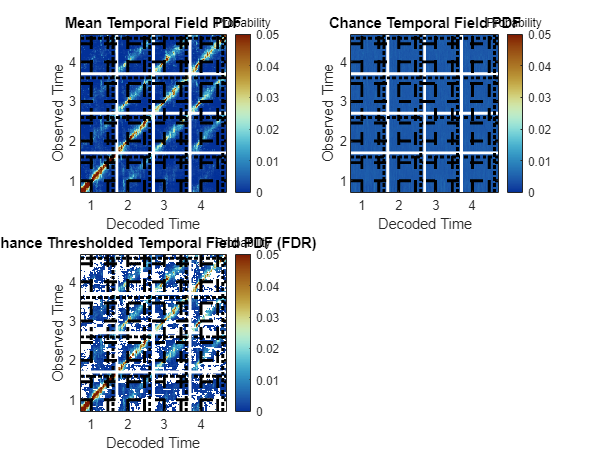

sps = nan(2);
figure; 
sps(1) = subplot(2,2,1);
tipALL_Real = cell2mat(cellfun(@(a){mean(a,3)},groupPostTIP_Real));
tipALL_RealMean = mean(tipALL_Real,3,'omitnan');
imagesc(tipALL_RealMean, postCLim);
set(gca, 'ydir', 'normal', 'xtick', piNdx, 'xticklabels', 1:mlb.seqLength,...
    'ytick', piNdx, 'yticklabels', 1:mlb.seqLength);
colormap(sps(1), cMap);
cb = colorbar(gca, 'eastoutside');
set(get(cb,'Title'),'String','Probability');
title('Mean Temporal Field PDF')
xlabel('Decoded Time');
ylabel('Observed Time');
hold on;
for ndx = 1:length(piNdx)
    plot(get(gca, 'xlim'),repmat(piNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(poNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(rwdNdx(ndx), [1,2]), ':k','linewidth', 2);

    plot(repmat(piNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(poNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(rwdNdx(ndx), [1,2]), get(gca, 'ylim'), ':k','linewidth', 2);

    if ndx<length(piNdx)
        plot(repmat(posNdx(ndx), [1,2]), get(gca, 'ylim'), '-w','linewidth', 2);
        plot(get(gca, 'xlim'),repmat(posNdx(ndx), [1,2]), '-w','linewidth', 2);
    end
end
sps(2) = subplot(2,2,2);
tipALL_Chance = cell2mat(groupPostTIP_FullChance(:,1));
imagesc(tipALL_Chance, postCLim);
set(gca, 'ydir', 'normal', 'xtick', piNdx, 'xticklabels', 1:mlb.seqLength,...
    'ytick', piNdx, 'yticklabels', 1:mlb.seqLength);
colormap(sps(2), cMap);
cb = colorbar(gca, 'eastoutside');
set(get(cb,'Title'),'String','Probability');
title('Chance Temporal Field PDF')
xlabel('Decoded Time');
ylabel('Observed Time');
hold on;
for ndx = 1:length(piNdx)
    plot(get(gca, 'xlim'),repmat(piNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(poNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(rwdNdx(ndx), [1,2]), ':k','linewidth', 2);

    plot(repmat(piNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(poNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(rwdNdx(ndx), [1,2]), get(gca, 'ylim'), ':k','linewidth', 2);

    if ndx<length(piNdx)
        plot(repmat(posNdx(ndx), [1,2]), get(gca, 'ylim'), '-w','linewidth', 2);
        plot(get(gca, 'xlim'),repmat(posNdx(ndx), [1,2]), '-w','linewidth', 2);
    end
end
tipSigVals = cell(size(groupPostTIP_Real));
for pos = 1:mlb.seqLength
    tempTIP_Real = groupPostTIP_Real{pos};
    tempSigVals = nan(size(tempTIP_Real,1), size(tempTIP_Real,2));
    for t1 = 1:size(tempTIP_Real,1)
        for t2 = 1:size(tempTIP_Real,2)
            [~,tempSigVals(t1,t2)] = ttest(squeeze(tempTIP_Real(t1,t2,:)), tempTIP_Real(t1,t2), 'Tail', 'Right');
        end
    end
    tipSigVals{pos} = tempSigVals;
end
tipSigVals = cell2mat(tipSigVals);
[~,q] = mafdr(tipSigVals(:));
sigLog = reshape(q,size(tipSigVals))<0.05;
% sigLog = tipSigVals<(0.05/numel(tipSigVals));
tipALL_RealMean(~sigLog) = nan;
sps(3) = subplot(2,2,3);
imagesc(tipALL_RealMean, postCLim);
colormap(sps(3),cMapNanW);
set(gca, 'ydir', 'normal', 'xtick', piNdx, 'xticklabels', 1:mlb.seqLength,...
    'ytick', piNdx, 'yticklabels', 1:mlb.seqLength);
cb = colorbar(gca, 'eastoutside');
set(get(cb,'Title'),'String','Probability');
title('Chance Thresholded Temporal Field PDF (FDR)')
xlabel('Decoded Time');
ylabel('Observed Time');
hold on;
for ndx = 1:length(piNdx)
    plot(get(gca, 'xlim'),repmat(piNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(poNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(rwdNdx(ndx), [1,2]), ':k','linewidth', 2);

    plot(repmat(piNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(poNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(rwdNdx(ndx), [1,2]), get(gca, 'ylim'), ':k','linewidth', 2);

    if ndx<length(piNdx)
        plot(repmat(posNdx(ndx), [1,2]), get(gca, 'ylim'), '-w','linewidth', 2);
        plot(get(gca, 'xlim'),repmat(posNdx(ndx), [1,2]), '-w','linewidth', 2);
    end
end

## Collapse Temporal Lag

tic;
transMatPosts = cell(mlb.seqLength);
transMatPost_TimeLagDiag = cell(mlb.seqLength);
transMatPost_TimeLagCDF = cell(mlb.seqLength);
transMatPost_MeanDiag = nan(mlb.seqLength,mlb.seqLength,numSeqs);

transMatChance = cell(mlb.seqLength);
transMatChance_TimeLagDiag = cell(mlb.seqLength);
transMatChance_TimeLagCDF = cell(mlb.seqLength);
transMatChance_MeanDiag = nan(mlb.seqLength, mlb.seqLength);
for p1 = 1:mlb.seqLength
    for p2 = 1:mlb.seqLength
        tempTIP_Post = groupPostTIP_Real{p1}(:,mlb.decodeIDvects(:,3)==p2,:);
        if trialWindowed 
            tempTrlMask = false(size(tempTIP_Post));
            tempTrlMask(mlb.obsvTimeVect>=0 & mlb.obsvTimeVect<=nearestPOtime, mlb.obsvTimeVect>=0 & mlb.obsvTimeVect<=nearestPOtime,:) = true;
            transMatPosts{p1,p2} = reshape(tempTIP_Post(tempTrlMask), [max(max(sum(tempTrlMask))),max(max(sum(tempTrlMask))),numSeqs]);
        else
            transMatPosts{p1,p2} = tempTIP_Post;
        end
        [transMatPost_TimeLagDiag{p1,p2}, tempLagVect, ~] = mlb.DiagonalLagMeanCollapse(transMatPosts{p1,p2});
        transMatPost_TimeLagCDF{p1,p2} = histcounts(mean(transMatPost_TimeLagDiag{p1,p2},1), size(transMatPost_TimeLagDiag{p1,p2},2), 'Normalization', 'cdf');
        transMatPost_MeanDiag(p1,p2,1:size(tempTIP_Post,3)) = transMatPost_TimeLagDiag{p1,p2}(:,tempLagVect==0); % ONLY the diagonal 
%         transMatPost_MeanDiag(p1,p2,:) = mean(transMatPost_TimeLagDiag{p1,p2}(:), 'omitnan'); % WHOLE quadrant

        tempTIP_Chance = groupPostTIP_FullChance{p1,1}(:,mlb.decodeIDvects(:,3)==p2);
        if trialWindowed
            transMatChance{p1,p2} = reshape(tempTIP_Chance(tempTrlMask(:,:,1)), [max(sum(tempTrlMask(:,:,1),1)), max(sum(tempTrlMask(:,:,1),1))]);
        else
            transMatChance{p1,p2} = tempTIP_Chance;
        end
        [transMatChance_TimeLagDiag{p1,p2}, tempLagVect, lagCounts] = mlb.DiagonalLagMeanCollapse(transMatChance{p1,p2});
        transMatChance_TimeLagCDF{p1,p2} = histcounts(transMatChance_TimeLagDiag{p1,p2}, size(transMatChance_TimeLagDiag{p1,p2},2), 'Normalization', 'cdf');
        transMatChance_MeanDiag(p1,p2) = transMatChance_TimeLagDiag{p1,p2}(:,tempLagVect==0); % ONLY the diagonal 
%         transMatChance_MeanDiag(p1,p2) = mean(transMatChance_TimeLagDiag{p1,p2}(:), 'omitnan'); % WHOLE quadrant
    end
end
toc

Elapsed time is 5.544862 seconds.


## Plot Temporal Lag Across Position

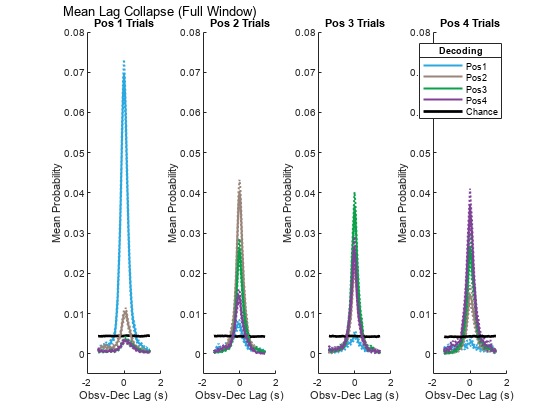

figure; 
sp = nan(1,mlb.seqLength);
plt = nan(1,mlb.seqLength+1);
for posObs = 1:mlb.seqLength
    sp(posObs) = subplot(1, mlb.seqLength, posObs);
    for posDec = 1:mlb.seqLength
        if trialWindowed
            plt(posDec) = mlb.PlotMeanVarLine(tempLagVect(lagCounts>=max(lagCounts/4))*mode(diff(mlb.obsvTimeVect)), transMatPost_TimeLagDiag{posObs, posDec}(:,lagCounts>=max(lagCounts/4)), 1, 0.05, mlb.PositionColors(posDec,:));
        else
            plt(posDec) = mlb.PlotMeanVarLine(tempLagVect(lagCounts>=max(lagCounts/2))*mode(diff(mlb.obsvTimeVect)), transMatPost_TimeLagDiag{posObs, posDec}(:,lagCounts>=max(lagCounts/2)), 1, 0.05, mlb.PositionColors(posDec,:));
        end
        if posObs==posDec
            if trialWindowed
                plt(mlb.seqLength+1) = plot(tempLagVect(lagCounts>=max(lagCounts/4))*mode(diff(mlb.obsvTimeVect)), transMatChance_TimeLagDiag{posObs,posDec}(lagCounts>=max(lagCounts/4)), '-k', 'linewidth', 2);
            else
                plt(mlb.seqLength+1) = plot(tempLagVect(lagCounts>=max(lagCounts/2))*mode(diff(mlb.obsvTimeVect)), transMatChance_TimeLagDiag{posObs,posDec}(lagCounts>=max(lagCounts/2)), '-k', 'linewidth', 2);
            end
        end
    end
    title(sprintf('Pos %i Trials',posObs));
    xlabel('Obsv-Dec Lag (s)');
    ylabel('Mean Probability');
end
linkaxes(sp, 'y')
if trialWindowed
    annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Mean Lag Collapse (Trial Period Only)',...
        'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');
else
    annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Mean Lag Collapse (Full Window)',...
        'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');
end
leg = legend(plt, [cellfun(@(a){sprintf('Pos%i',a)}, num2cell(1:4,[1,4])), {'Chance'}]);
set(get(leg, 'Title'), 'String', 'Decoding')

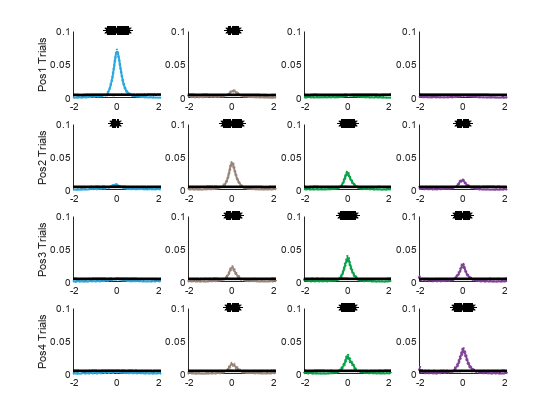

figure;
sp = nan(mlb.seqLength);
for posObs = 1:mlb.seqLength
    for posDec = 1:mlb.seqLength
        tempObsv = transMatPost_TimeLagDiag{posObs,posDec}(:,lagCounts>=max(lagCounts/4));
        tempChance = transMatChance_TimeLagDiag{posObs,posDec}(lagCounts>=max(lagCounts/4));
        sp(posObs,posDec) = subplot(mlb.seqLength, mlb.seqLength, sub2ind([mlb.seqLength, mlb.seqLength], posDec, posObs));
        tempSigVect = false(1,size(tempObsv,2));
        for t = 1:size(tempObsv,2)
            tempSigVect(t) = ttest(tempObsv(:,t), tempChance(t), 'Alpha', 0.05/size(tempObsv,2), 'Tail', 'Right');
%             tempSigVect(t) = ttest(tempObsv(:,t), tempChance(t), 'Alpha', 0.05, 'Tail', 'Right');
        end
        mlb.PlotMeanVarLine(tempLagVect(lagCounts>=max(lagCounts/4))*mode(diff(mlb.obsvTimeVect)), tempObsv, 1, 0.05, mlb.PositionColors(posDec,:));
        tempSigVect = tempSigVect.*0.1;
        tempSigVect(tempSigVect==0) = nan;
        scatter(tempLagVect(lagCounts>=max(lagCounts/4))*mode(diff(mlb.obsvTimeVect)), tempSigVect,'*', 'k');
        hold on;
        plot(tempLagVect(lagCounts>=max(lagCounts/4))*mode(diff(mlb.obsvTimeVect)), tempChance, 'k', 'linewidth', 2)
    end
end
linkaxes(sp, 'xy');
for pos = 1:mlb.seqLength
    ylabel(sp(pos,1), sprintf('Pos%i Trials', pos));
end

## TransMat Mean Diagonal Decoding vs Chance

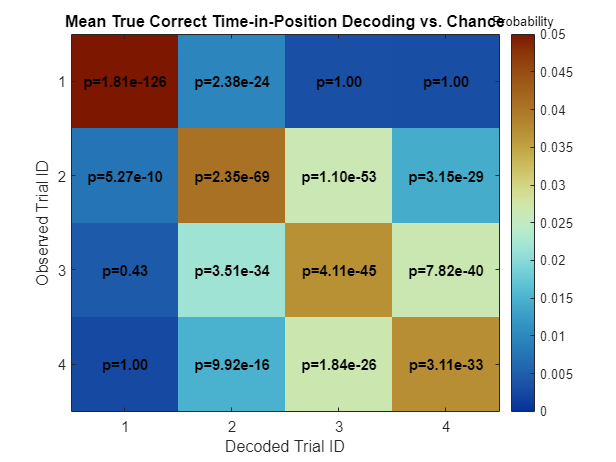

figure;
imagesc(mean(transMatPost_MeanDiag,3,'omitnan'), postCLim);
colormap(cMap)
cb = colorbar(gca, 'eastoutside');
set(get(cb,'Title'),'String','Probability');
title('Mean True Correct Time-in-Position Decoding vs. Chance')
set(gca, 'xtick', 1:mlb.seqLength, 'ytick', 1:mlb.seqLength)
xlabel('Decoded Trial ID');
ylabel('Observed Trial ID');
for oPos = 1:mlb.seqLength
    for dPos = 1:mlb.seqLength
        [h,p] = ttest(squeeze(transMatPost_MeanDiag(oPos,dPos,:)), transMatChance_MeanDiag(oPos,dPos), 'Alpha', 0.05/4, 'Tail', 'Right');
        if p<0.05
            text(dPos,oPos, sprintf('p=%.02i',p), 'FontSize', 10, 'FontWeight', 'Bold', 'HorizontalAlignment','center');
        else
            text(dPos,oPos, sprintf('p=%.02f',p), 'FontSize', 10, 'FontWeight', 'Bold', 'HorizontalAlignment','center');
        end
    end
end

## TransMat Mean Diagonal Decoding ANOVAs

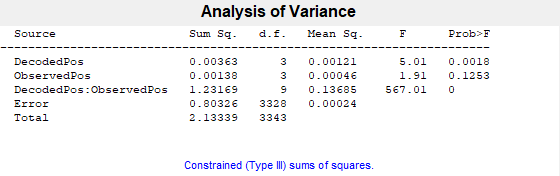

p =     0.0018
    0.1253
         0


tbl = 6×7 cell array
    {'Source'                }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'  }
    {'DecodedPos'            }    {[ 0.0036]}    {[   3]}    {[        0]}    {[    0.0012]}    {[  5.0084]}    {[  0.0018]}
    {'ObservedPos'           }    {[ 0.0014]}    {[   3]}    {[        0]}    {[4.6160e-04]}    {[  1.9125]}    {[  0.1253]}
    {'DecodedPos:ObservedPos'}    {[ 1.2317]}    {[   9]}    {[        0]}    {[    0.1369]}    {[567.0058]}    {[       0]}
    {'Error'                 }    {[ 0.8033]}    {[3328]}    {[        0]}    {[2.4136e-04]}    {0×0 double}    {0×0 double}
    {'Total'                 }    {[ 2.1334]}    {[3343]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double}


stats = struct with fields:
         source: 'anovan'
          resid: [-0.0653 0.0096 0.0051 -0.0015 -0.0082 -0.0265 -0.0140 -0.0101 -0.0034 -0.0228 -0.0309 -0.0241 2.9142e-04 0.0089 -0.0155 -0.0233 -0.0695 -0.0035 -0.0030 0.0082 -0.0097 -0.0278 -0.0148 -0.0117 -0.0035 -0.0167 -0.0163 -0.0084 0.0030 … ]
         coeffs: [25×1 double]
            Rtr: [16×16 double]
       rowbasis: [16×25 double]
            dfe: 3328
            mse: 2.4136e-04
    nullproject: [25×16 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {25×1 cell}
           vars: [25×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: [4×4 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


terms =      1     0
     0     1
     1     1


obsvPosID = repmat((1:mlb.seqLength)',[1, mlb.seqLength, numSeqs]);
decodePosID = repmat(1:mlb.seqLength,[mlb.seqLength,1, numSeqs]);
tempLagMtx = nan(mlb.seqLength);
for lag = 1:length(mlb.lagVect)
    tempLagMtx(triu(true(mlb.seqLength),mlb.lagVect(lag)) & tril(true(mlb.seqLength),mlb.lagVect(lag))) = mlb.lagVect(lag);
end
odLagID = repmat(tempLagMtx, [1,1,numSeqs]);
% [p,tbl,stats,terms] = anovan(transMatPost_MeanDiag(:),{decodePosID(:), obsvPosID(:), odLagID(:)}, 'model', 'full', 'varnames',{'DecodedPos', 'ObservedPos', 'Lag'}, 'SSType', 1)
[p,tbl,stats,terms] = anovan(transMatPost_MeanDiag(:),{decodePosID(:), obsvPosID(:)}, 'model', 'full', 'varnames',{'DecodedPos', 'ObservedPos'}, 'SSType', 3)

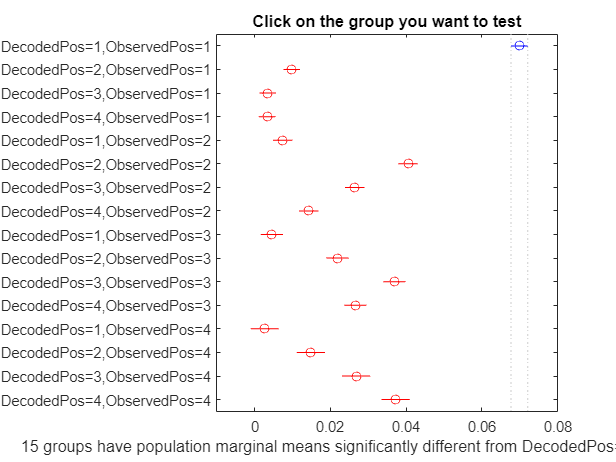

opC =     1.0000    2.0000    0.0558    0.0601    0.0644         0
    1.0000    3.0000    0.0621    0.0664    0.0707         0
    1.0000    4.0000    0.0623    0.0666    0.0709         0
    1.0000    5.0000    0.0577    0.0624    0.0672         0
    1.0000    6.0000    0.0246    0.0294    0.0341    0.0000
    1.0000    7.0000    0.0387    0.0434    0.0482    0.0000
    1.0000    8.0000    0.0509    0.0556    0.0604    0.0000
    1.0000    9.0000    0.0602    0.0653    0.0705         0
    1.0000   10.0000    0.0429    0.0480    0.0532    0.0000
    1.0000   11.0000    0.0278    0.0330    0.0382    0.0000


figure; 
opC = multcompare(stats, 'Dimension', [2 1], 'CriticalValueType','bonferroni')

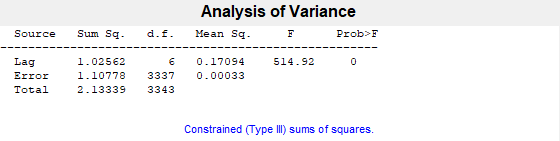

p = 0

tbl = 4×7 cell array
    {'Source'}    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'  }
    {'Lag'   }    {[ 1.0256]}    {[   6]}    {[        0]}    {[    0.1709]}    {[514.9201]}    {[       0]}
    {'Error' }    {[ 1.1078]}    {[3337]}    {[        0]}    {[3.3197e-04]}    {0×0 double}    {0×0 double}
    {'Total' }    {[ 2.1334]}    {[3343]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double}


stats = struct with fields:
         source: 'anovan'
          resid: [-0.0461 4.5263e-04 0.0010 -0.0015 -0.0174 -0.0367 -0.0088 -0.0039 -0.0078 -0.0154 -0.0447 -0.0139 2.9142e-04 0.0153 -0.0079 -0.0367 -0.0503 -0.0127 -0.0071 0.0082 -0.0189 -0.0380 -0.0095 -0.0055 -0.0079 -0.0092 -0.0302 0.0018 0.0030 … ]
         coeffs: [8×1 double]
            Rtr: [7×7 double]
       rowbasis: [7×8 double]
            dfe: 3337
            mse: 3.3197e-04
    nullproject: [8×7 double]
          terms: 1
        nlevels: 7
     continuous: 0
         vmeans: 0
       termcols: [2×1 double]
     coeffnames: {8×1 cell}
           vars: [8×1 double]
       varnames: {'Lag'}
       grpnames: {{7×1 cell}}
        vnested: []
            ems: [2×2 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


terms = 1


[p,tbl,stats,terms] = anovan(transMatPost_MeanDiag(:),{odLagID(:)}, 'varnames', 'Lag', 'SSType', 3)

tbl{2,7}

ans = 0

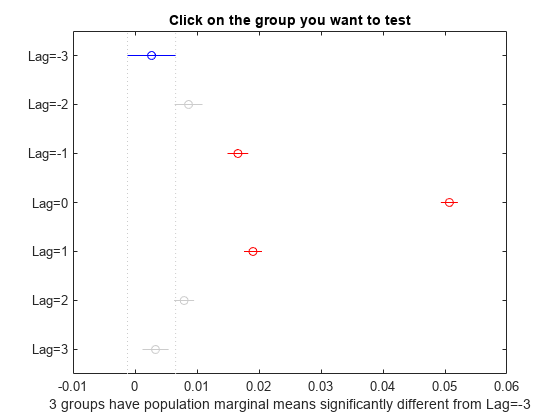

ans =     1.0000    2.0000   -0.0119   -0.0060    0.0000    0.0505
    1.0000    3.0000   -0.0195   -0.0139   -0.0083    0.0000
    1.0000    4.0000   -0.0534   -0.0480   -0.0426         0
    1.0000    5.0000   -0.0218   -0.0164   -0.0109    0.0000
    1.0000    6.0000   -0.0108   -0.0052    0.0003    0.0785
    1.0000    7.0000   -0.0065   -0.0006    0.0052    0.9999
    2.0000    3.0000   -0.0119   -0.0080   -0.0040    0.0000
    2.0000    4.0000   -0.0457   -0.0421   -0.0384         0
    2.0000    5.0000   -0.0141   -0.0104   -0.0066    0.0000
    2.0000    6.0000   -0.0032    0.0007    0.0046    0.9982


multcompare(stats)